# Poisson Equation

A general partial differential equation in the PDE toolbox form is 


$$ m\frac{\partial^2 u}{\partial t^2} + d\frac{\partial u}{\partial t} -\mathop{div}(c\nabla u) + au = f.$$


A Poisson equation in the toolbox form is


$$ -\mathop{div}(c\nabla u) = f,$$


where $m=0, d=0, a=0.$

#### Create the geometry $\Omega$

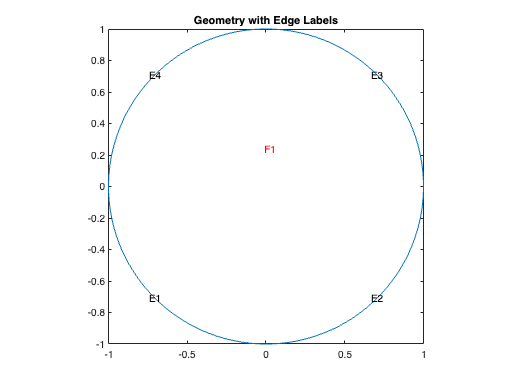

circle = [1;0;0;1];
gd = [circle];
ns = char('circle')';
sf = 'circle';
g = decsg(gd,sf,ns);
pdegplot(g,'EdgeLabels','on','FaceLabels','on') 
xlim([-1.2,1.2])
axis equal
title 'Geometry with Edge Labels';

#### Linear Poisson Equation

Solve the solution to the following Poisson equation:


$$ -\mathop{div}(\nabla u) = 1,\\
u|_{\partial \Omega} = 0.$$


- To solve the linear Poisson equation using the programmatic workflow, first create a PDE model.

numberOfPDE = 1;
model = createpde(numberOfPDE);

          2.  Include the geometry in the model.

geometryFromEdges(model,g);

          3. Specify the coefficients.

m = 0;
d = 0;
c = 1;
a = 0;
f = 1;
specifyCoefficients(model,'m',m,'d',d,'c',c,'a',a,'f',f);

          4. Specify the boundary conditions using the function $u(x,y) = x^2$.

applyBoundaryCondition(model,'dirichlet', 'Edge',1:model.Geometry.NumEdges,'u',0);

          5. Generate a mesh 

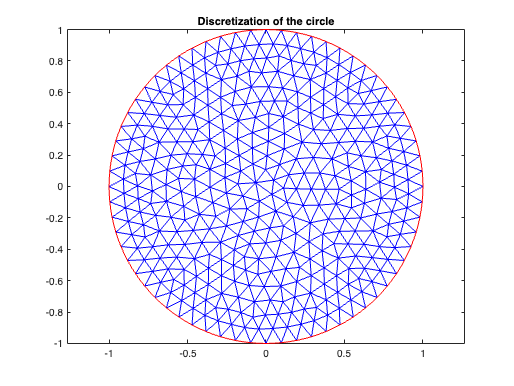

generateMesh(model,'Hmax',0.1);
figure; 
pdemesh(model); 
axis equal
title 'Discretization of the circle'

          6. Solve the problem by using the `solvepde` function. Because the problem is nonlinear, `solvepde` invokes a nonlinear solver. Observe the solver progress by setting the `SolverOptions.ReportStatistics` property of the model to `'on'`.

model.SolverOptions.ReportStatistics = 'on';
result = solvepde(model);
u = result.NodalSolution;

           7. Plot the solution.

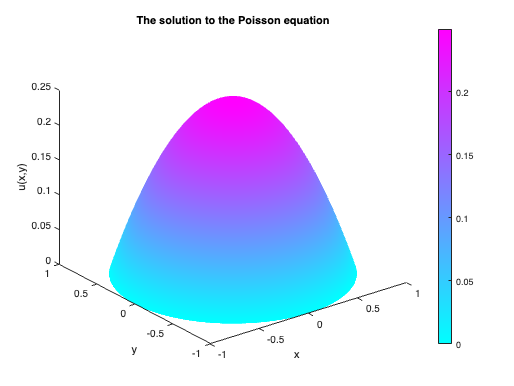

figure; 
pdeplot(model,'XYData',u,'ZData',u);
xlabel 'x'
ylabel 'y'
zlabel 'u(x,y)'
title 'The solution to the Poisson equation'

#### Poisson Equation applied to solve Minimal Surface Problem

This example shows how to solve the minimal surface equation


$$-\nabla \cdot \left( \nabla u \right) = 0$$


on the unit disk $\Omega =\left\lbrace \left(x,y\right)\left|x^2 +y^2 \le 1\right.\right\rbrace$, with $$u(x,y) = \vert xy \vert$$ on the boundary $\partial \Omega$. 

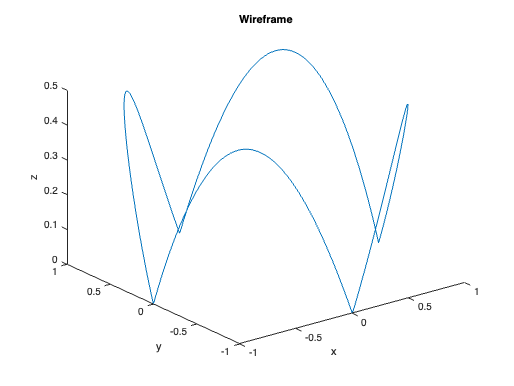

figure;
theta=0:0.01:2*pi;
x=cos(theta); 
y=sin(theta); 
z= abs(x.*y);
plot3(x,y,z);
xlabel 'x'
ylabel 'y'
zlabel 'z'
title 'Wireframe'

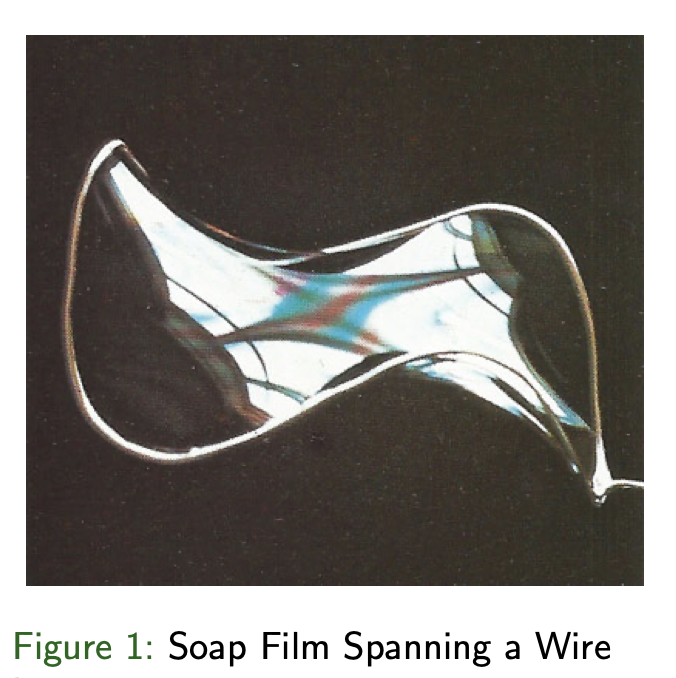

Therefore, for the minimal surface problem, the coefficients are as follows:


$$c = 1.$$


Because the coefficient $c$ is a function of the solution $u$, the minimal surface problem is a Poisson problem.

To solve the minimal surface problem using the programmatic workflow, first create a PDE model with a single dependent variable.

numberOfPDE = 1;
model = createpde(numberOfPDE);

 Create the geometry and include it in the model. The `circleg` function represents this geometry.

geometryFromEdges(model,g);

Specify the coefficients.

m = 0;
d = 0;
%c = @(region,state) 1./sqrt(1+state.ux.^2 + state.uy.^2);
c = 1;
a = 0;
f = 0;
specifyCoefficients(model,'m',m,'d',d,'c',c,'a',a,'f',f);

Specify the boundary conditions using the function $$u(x,y) = \vert xy \vert$$.

bcMatrix = @(region,~) abs(region.x.*region.y); %region.x.^2;
applyBoundaryCondition(model,'dirichlet',...
                             'Edge',1:model.Geometry.NumEdges,...
                             'u',bcMatrix);

Generate a mesh.

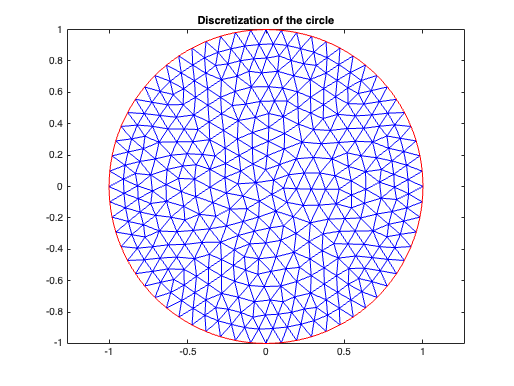

generateMesh(model,'Hmax',0.1);
figure; 
pdemesh(model); 
axis equal
title 'Discretization of the circle'

Solve the problem by using the `solvepde` function. Because the problem is nonlinear, `solvepde` invokes a nonlinear solver. Observe the solver progress by setting the `SolverOptions.ReportStatistics` property of the model to `'on'`.

model.SolverOptions.ReportStatistics = 'on';
result = solvepde(model);
u = result.NodalSolution;

Plot the solution.

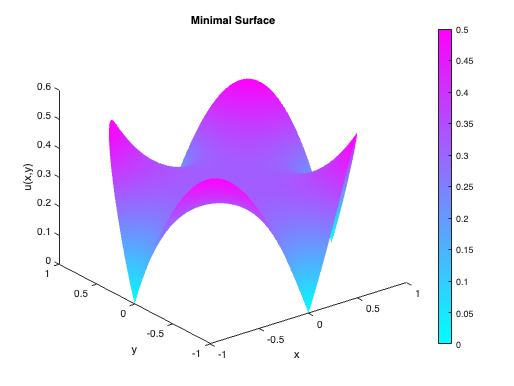

figure; 
pdeplot(model,'XYData',u,'ZData',u);
xlabel 'x'
ylabel 'y'
zlabel 'u(x,y)'
title 'Minimal Surface'

#### Exercise:

Could you find minimal surface of chip?

Hint: $u(x,y) = x^2$ on the boundary $\partial \Omega$.

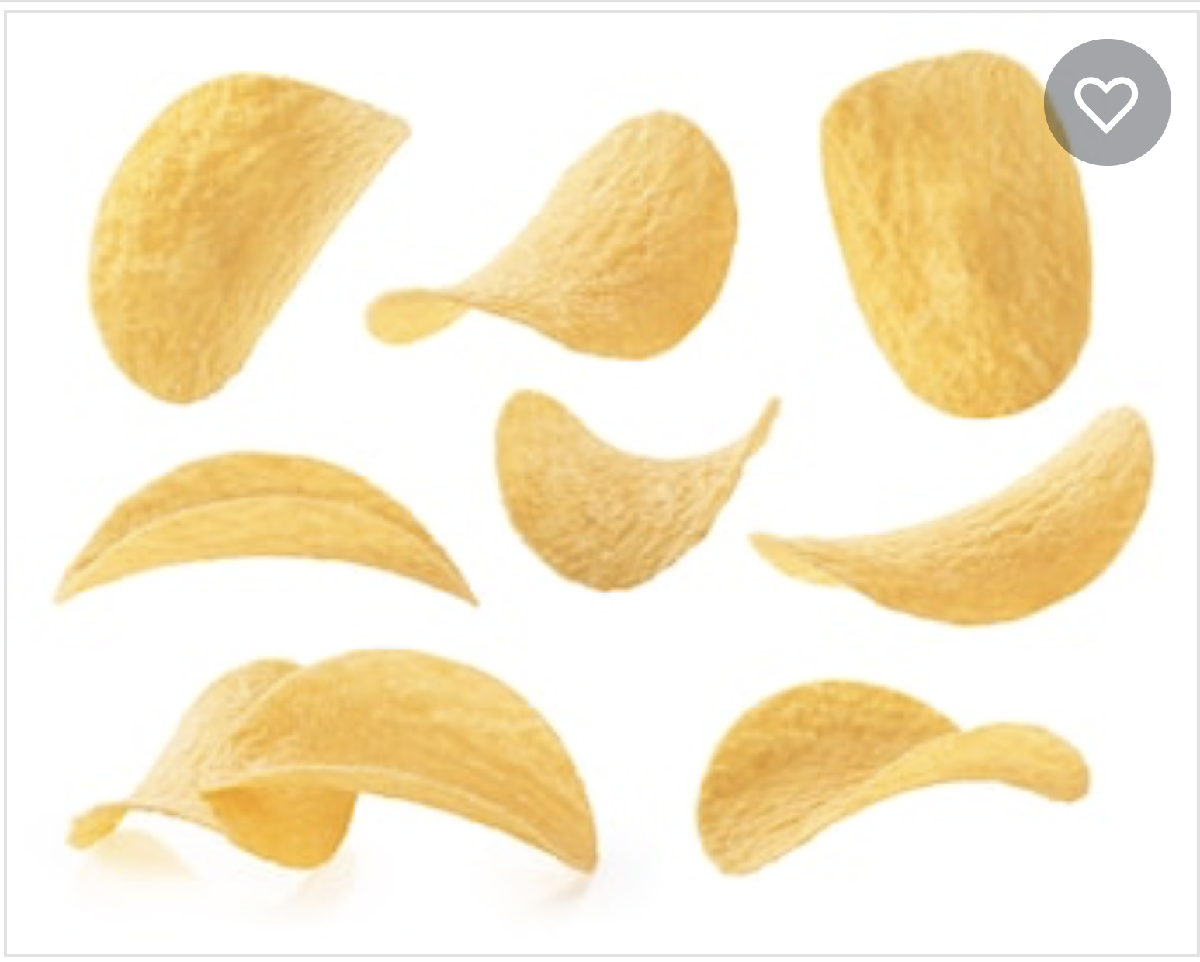

Reference: *Partial Differential Equation ToolboxTM User's Guide *